Task 1

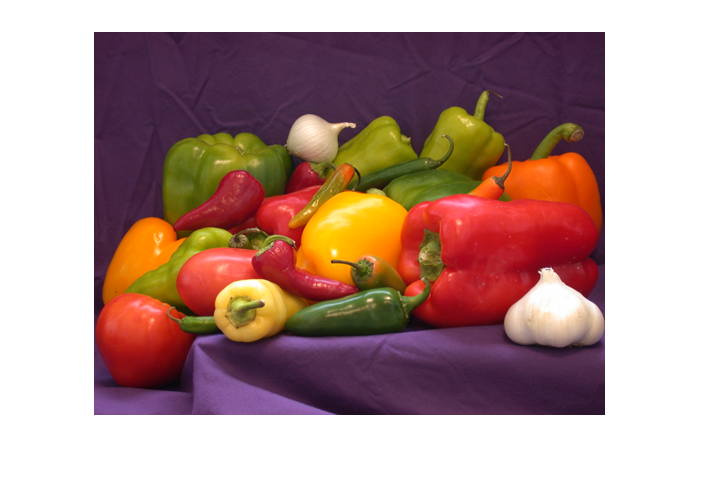

clear all
close all


imshow("peppers.png")

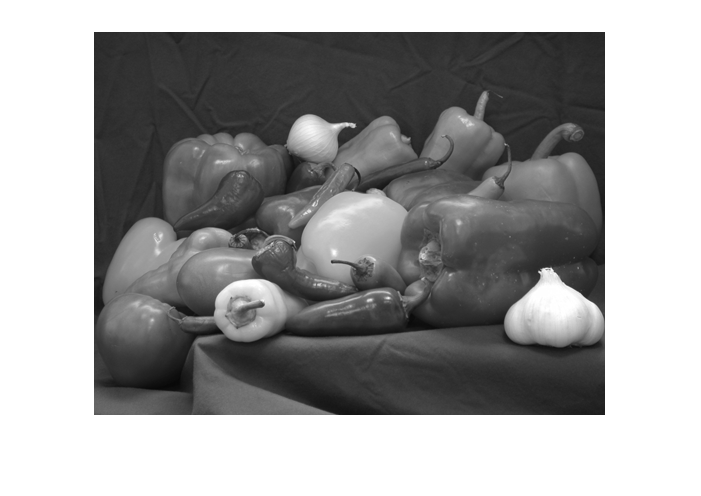

I=imread("peppers.png");

I1=rgb2gray(I);
imshow(I1)

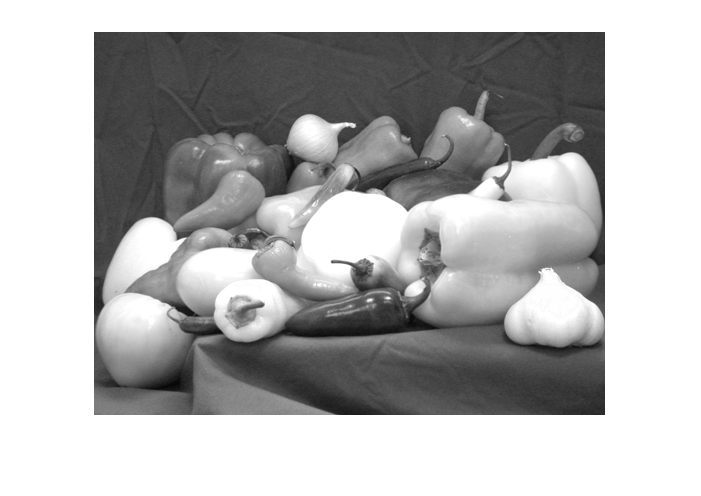


IR=I(:,:,1);
imshow(IR)

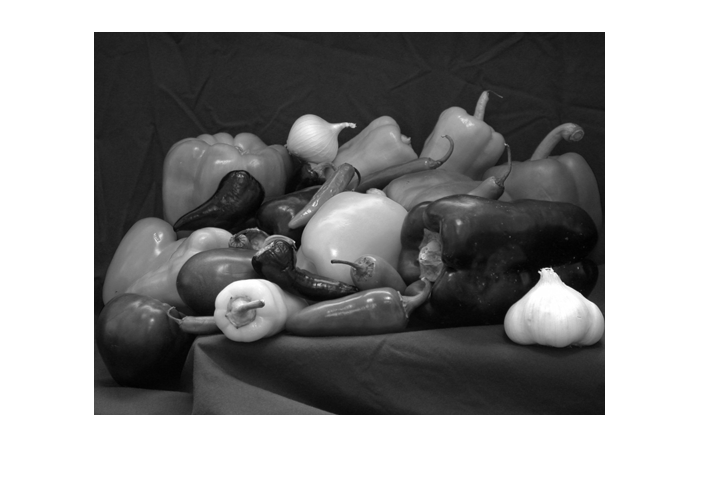


IG=I(:,:,2);
imshow(IG)

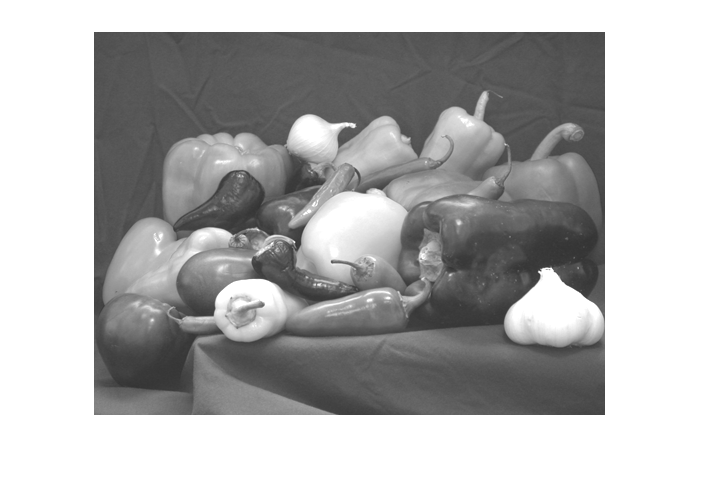


IG2=IG+50;
imshow(IG2)

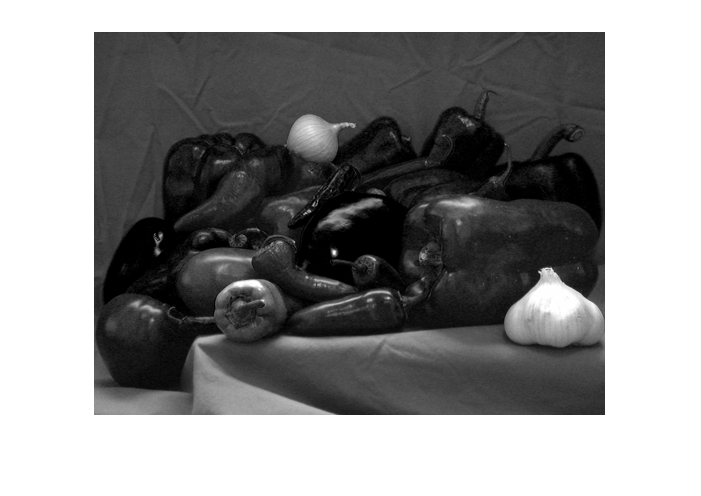



IB=I(:,:,3);
imshow(IB)

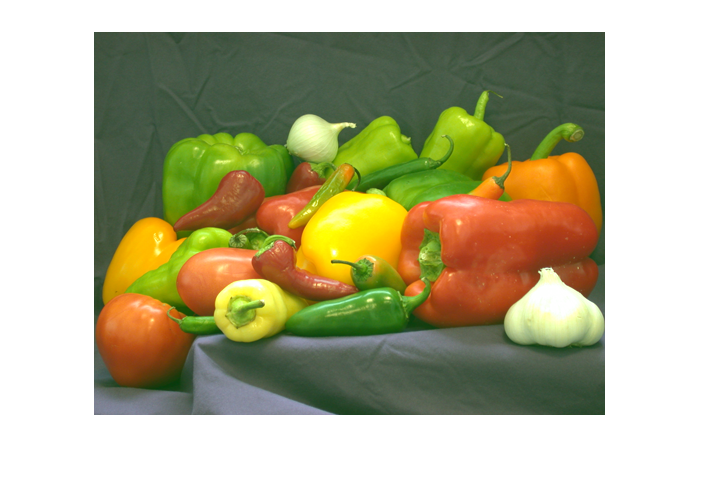


I2=cat(3,IR,IG2,IB);
imshow(I2)


disp("B,G,R")

B,G,R


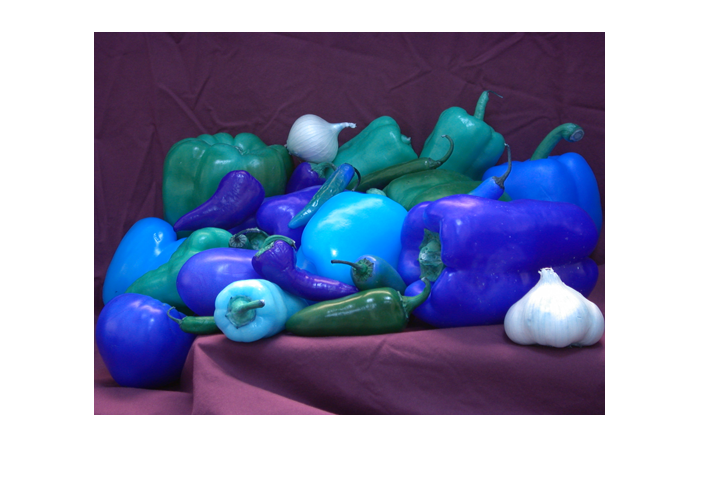

I3=cat(3,IB,IG,IR);
imshow(I3)

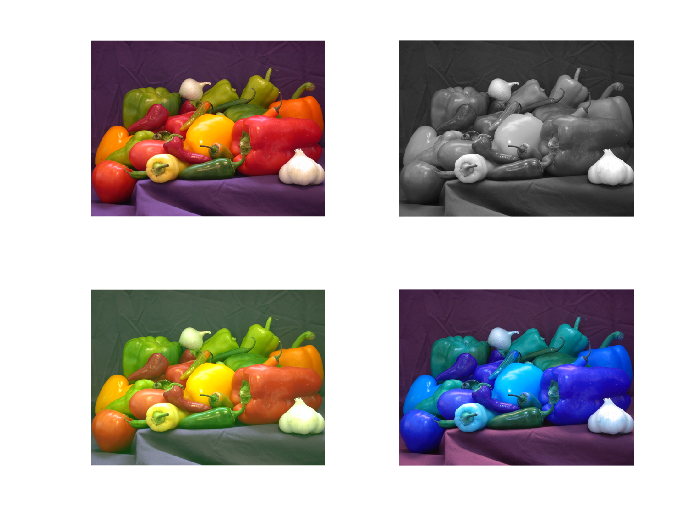


figure(2)

plot5=subplot(2,2,1);
imshow(I);
hold on

plot6=subplot(2,2,2);
imshow(I1);
hold on

plot7=subplot(2,2,3);
imshow(I2);
hold on

plot8=subplot(2,2,4);
imshow(I3);
hold off

Task 2

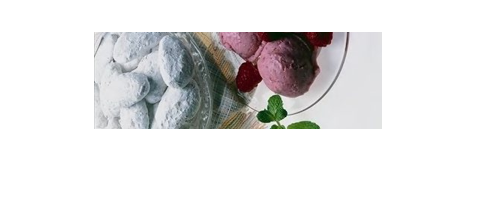

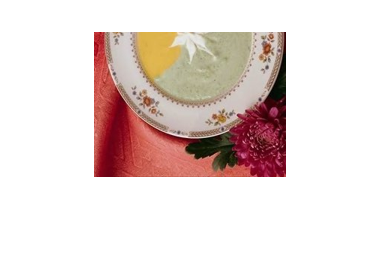

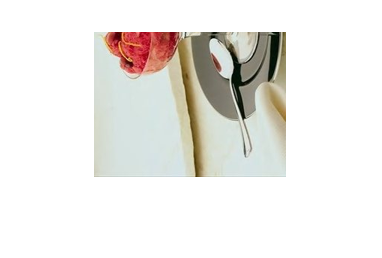

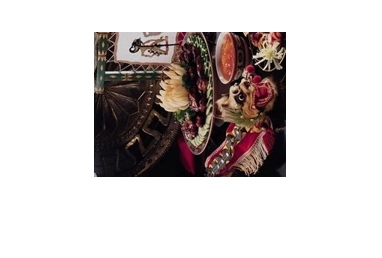

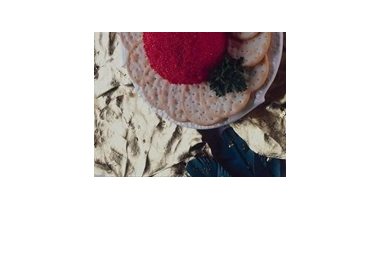

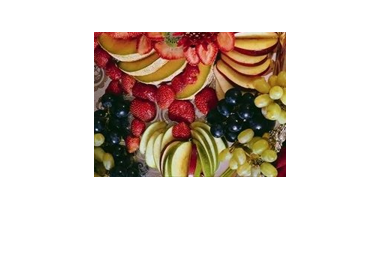

clear all
close all

batchProcessing()

Task 3

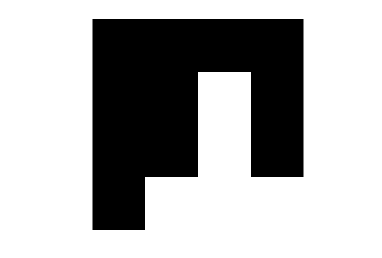

img = [0 0 0 0 0 0 0 1 1 0;
       1 0 0 1 0 0 1 0 0 1;
       1 0 0 1 0 1 1 0 0 0;
       0 0 1 1 1 0 0 0 0 0;
       0 0 1 1 1 0 0 1 1 1];

S1 = img(1:4,2:5);
S2 = img(1:4,6:9);
imshow(S1,'InitialMagnification',"fit")

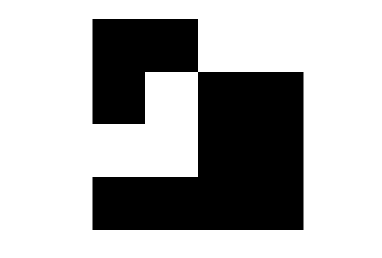

imshow(S2,'InitialMagnification',"fit")

fprintf('non zero elements in S1 are : %d', counting(S1));

non zero elements in S1 are : 5

fprintf('non zero elements in S2 are : %d', counting(S2));

non zero elements in S2 are : 5

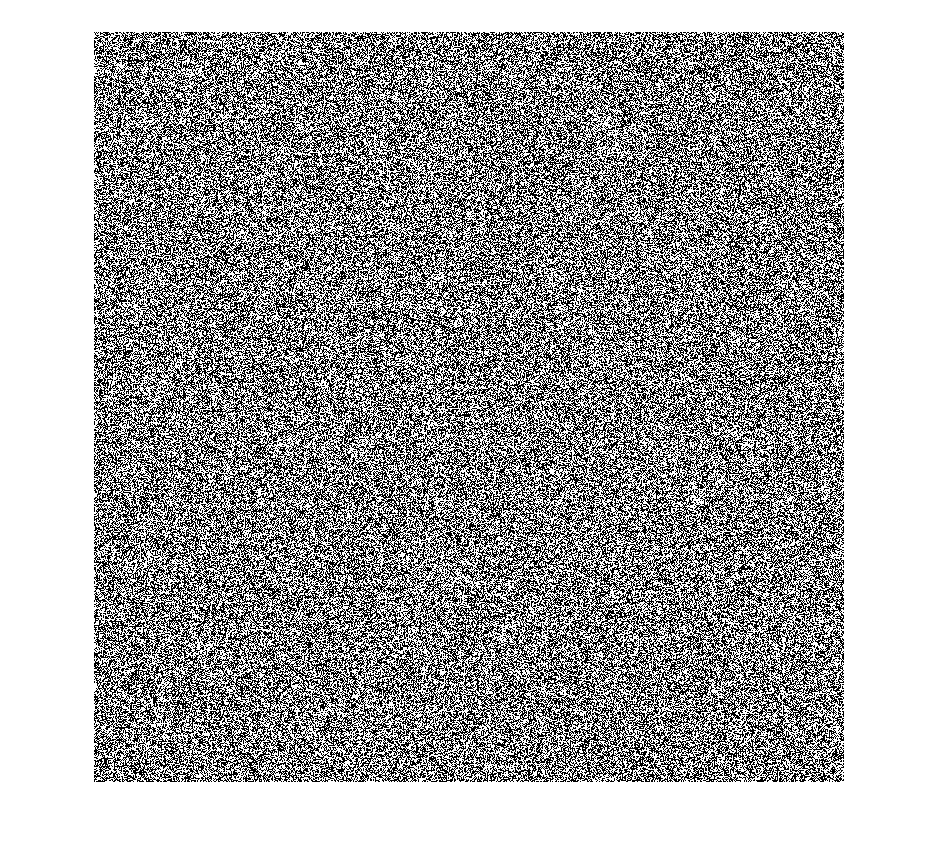

load S.mat
figure, imshow(S)

fprintf('non zero elements for S are : %d', counting(S));

non zero elements for S are : 4496982

function z=counting(s)
z=sum(s(:)~=0);

end


